# **QIBC analysis**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'DMSO',[2:7],2,1:25,[0 0 0]; %1    
        'DOX',[2:7],4,1:25,[0 0 0]; %1    

    };


 load([dataDir filesep 'C228_data.mat'],'S');
% S = loadData_IF(conditions, dataDir);


**Compare histograms **

conds = [1 2];

yval = 'FarRed1';

gateVals = {'YFP1', 'dna'};
rangeVals = {[2^6.5 Inf], [0 2^20]}; 

data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    if condition == 2
        totalGate = totalGate & S(condition).RFP1 > 2^10;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

gateVals = {};
rangeVals = {};
condition = 1;
ydata = log2(S(condition).(yval));

totalGate = true(size(ydata,1),1);
for gate = 1:size(gateVals,2)
    gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
    totalGate = totalGate  & gateInds;
end

ydata = ydata(totalGate);
data = [data {ydata}];


figure('Units', 'Inches', 'Position', [0, 0, 4, 5])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(3))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','separate','xlabel','log2[EdU (RFU)]','FontSize',16)

ans = 1×3 cell array
    {'Plot #1: '}    {'Plot #2: '}    {'Plot #3: '}


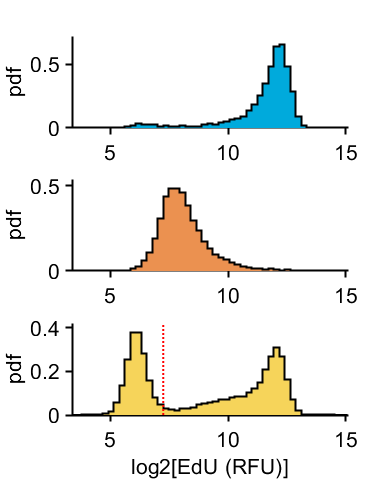

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\eduhists.pdf'])
vline(7.25)

data

data = 1×3 cell array
    {5317×1 double}    {8776×1 double}    {56309×1 double}


**Compare histograms **

conds = [1 2];

yval = 'RFP1';

gateVals = {'RFP1'};
rangeVals = {[2^3 Inf], [0 2^20]}; 

data = {};

for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    ydata = ydata(totalGate);
    
    data = [data {ydata}];

end

figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(2))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','noerror','xlabel','log2[Cdt1 (RFU)]','FontSize',16)

ans = 1×2 cell array
    {'Plot #1: '}    {'Plot #2: '}


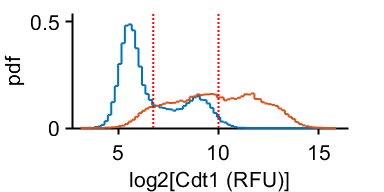

% axis square
% xlim([2.75 16])
% pbaspect([2.5 1 1])
vline([ 6.75 10])
print_pdf([pwd() '\Figs\cdt1hists.pdf'])


data

data = 1×2 cell array
    {56309×1 double}    {57484×1 double}


**Compare histograms **

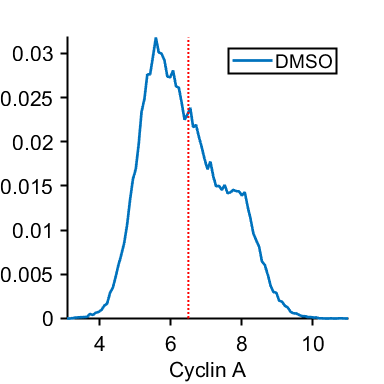

conds = [1 ];

yval = 'YFP1';

gateVals = {};
rangeVals = {[2^5 2^11]}; 

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).(yval)); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
%     edges = linspace(17,22.5,100);
    edges = linspace(3,11,100);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2);
end
legend(conditions(conds,1));
xlabel('Cyclin A')
hold off
% title('Geminin')
set(gca,'FontSize',16)
axis square
vline(6.5)